clc;clear;
workingpath='/Volumes/WD_D/gufei/monkey_data/campwater';
cd(workingpath);

files=dir('*side.csv');
alldata=cell(1,length(files));
% middle point
m=zeros(1,length(files));
conditions=cell(1,length(files));
for f=1:length(files)
    % load data
    filename=files(f).name;
    % replace _ with -
    conditions{f}=strrep(filename(1:end-9),'_','-');
    % 从第二行第一列读取数据
    data=csvread(filename,1,0);
    m(f)=mean([min(data(:,2)) max(data(:,2))]);
    disp(filename)
    disp([min(data(:,2)) mean([min(data(:,2)) max(data(:,2))]) max(data(:,2)) min(data(:,3)) mean([min(data(:,3)) max(data(:,3))]) max(data(:,3))])
    % y is reversed
    data(:,3)=140-data(:,3);
    % 绘制轨迹
    % monkeyt(data(:,2),data(:,3),0.1,0.001);
    % 查看分布情况
    % length(data(data(:,2)>100,3));
    % length(data(data(:,2)<=100,3));
    % 
    % length(data(data(:,2)<=90,3));
    % length(data(data(:,2)>=110,3));
    % 
    % length(data(data(:,2)<=80,3));
    % length(data(data(:,2)>=120,3));
    % max(data(:,2));
    % min(data(:,2));
    % mean([max(data(:,2)),min(data(:,2))]);
    %保存到cell中
    alldata{f}=data;
end

吲哚_L_20201001_side.csv


   23.1664  122.3482  221.5300   60.9055   96.1718  131.4380



吲哚_R_20200930_side.csv


   21.9848  121.9749  221.9650   70.9609  100.5874  130.2140



异戊酸_L_20200929_side.csv


   19.6015  117.5563  215.5110   66.9861   97.6945  128.4030



异戊酸_R_20200926_side.csv


   23.3736  122.8108  222.2480   67.8863   99.7327  131.5790



白桃_L_20201003_side.csv


   19.3473  113.9021  208.4570   71.3002  100.3326  129.3650



白桃_R_20201004_side.csv


   18.9209  112.4839  206.0470   72.9749  100.4169  127.8590



香蕉_L_20201008_side.csv


   56.0087  110.5508  165.0930   80.2424   95.7127  111.1830



香蕉_R_20201009_side.csv


   20.6690  123.1115  225.5540   57.2239   94.2035  131.1830



## Scale

for f=1:length(files)
    data=alldata{f};
    mid=m(f);
    minvalue=min(data(:,2));
    maxvalue=max(data(:,2));
    data(data(:,2)<=mid,2)=(data(data(:,2)<=mid,2)-minvalue)*100/(mid-minvalue);    
    data(data(:,2)>mid,2)=100+(data(data(:,2)>mid,2)-mid)*100/(maxvalue-mid);    
    alldata{f}=data;
end

## 绘制轨迹

% for f=1:length(files)
%     data=alldata{f};
%     figure;
%     % 绘制轨迹
%     % monkeyt(data(:,2),data(:,3),0.1,0.001);
%     monkeyt(data(:,2),data(:,3),0,0);
%     title(conditions{f});
% end

## 整体的直方图

吲哚-L-20201001


   100   100



pvalue = 0

st =     chi2stat: 2.6316e+04
          df: 1
       edges: [0 100 200]
           O: [70001 21051]
           E: [45526 45526]


    90   110



pvalue = 0

st =     chi2stat: 2.7371e+04
          df: 1
       edges: [0 100 200]
           O: [69326 19906]
           E: [44616 44616]


    80   120



pvalue = 0

st =     chi2stat: 3.0080e+04
          df: 1
       edges: [0 100 200]
           O: [68785 17762]
           E: [4.3274e+04 4.3274e+04]


吲哚-R-20200930


   100   100



pvalue = 0

st =     chi2stat: 1.0479e+04
          df: 1
       edges: [0 100 200]
           O: [61363 30360]
           E: [4.5862e+04 4.5862e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.0758e+04
          df: 1
       edges: [0 100 200]
           O: [60759 29584]
           E: [4.5172e+04 4.5172e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.1667e+04
          df: 1
       edges: [0 100 200]
           O: [60110 28040]
           E: [44075 44075]


异戊酸-L-20200929


   100   100



pvalue = 0

st =     chi2stat: 1.5679e+04
          df: 1
       edges: [0 100 200]
           O: [63861 26269]
           E: [45065 45065]


    90   110



pvalue = 0

st =     chi2stat: 1.5793e+04
          df: 1
       edges: [0 100 200]
           O: [63404 25858]
           E: [44631 44631]


    80   120



pvalue = 0

st =     chi2stat: 1.8163e+04
          df: 1
       edges: [0 100 200]
           O: [62956 23361]
           E: [4.3158e+04 4.3158e+04]


异戊酸-R-20200926


   100   100



pvalue = 0

st =     chi2stat: 7.3309e+03
          df: 1
       edges: [0 100 200]
           O: [62716 35837]
           E: [4.9276e+04 4.9276e+04]


    90   110



pvalue = 0

st =     chi2stat: 7.5099e+03
          df: 1
       edges: [0 100 200]
           O: [62208 35166]
           E: [48687 48687]


    80   120



pvalue = 0

st =     chi2stat: 9.1177e+03
          df: 1
       edges: [0 100 200]
           O: [61365 32163]
           E: [46764 46764]


白桃-L-20201003


   100   100



pvalue = 0

st =     chi2stat: 1.7864e+04
          df: 1
       edges: [0 100 200]
           O: [66455 25848]
           E: [4.6152e+04 4.6152e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.7004e+04
          df: 1
       edges: [0 100 200]
           O: [63794 24948]
           E: [44371 44371]


    80   120



pvalue = 0

st =     chi2stat: 1.8063e+04
          df: 1
       edges: [0 100 200]
           O: [62077 22899]
           E: [42488 42488]


白桃-R-20201004


   100   100



pvalue = 0

st =     chi2stat: 1.9502e+04
          df: 1
       edges: [0 100 200]
           O: [72541 28214]
           E: [5.0378e+04 5.0378e+04]


    90   110



pvalue = 0

st =     chi2stat: 2.0618e+04
          df: 1
       edges: [0 100 200]
           O: [71846 26757]
           E: [4.9302e+04 4.9302e+04]


    80   120



pvalue = 0

st =     chi2stat: 2.2556e+04
          df: 1
       edges: [0 100 200]
           O: [70754 24421]
           E: [4.7588e+04 4.7588e+04]


香蕉-L-20201008


   100   100



pvalue = 0

st =     chi2stat: 2.3499e+04
          df: 1
       edges: [0 100 200]
           O: [69537 22924]
           E: [4.6230e+04 4.6230e+04]


    90   110



pvalue = 0

st =     chi2stat: 2.4003e+04
          df: 1
       edges: [0 100 200]
           O: [68543 21940]
           E: [4.5242e+04 4.5242e+04]


    80   120



pvalue = 0

st =     chi2stat: 2.4932e+04
          df: 1
       edges: [0 100 200]
           O: [67629 20701]
           E: [44165 44165]


香蕉-R-20201009


   100   100



pvalue = 1.7742e-38

st =     chi2stat: 168.2609
          df: 1
       edges: [0 100 200]
           O: [47053 43157]
           E: [45105 45105]


    90   110



pvalue = 7.1675e-39

st =     chi2stat: 170.0632
          df: 1
       edges: [0 100 200]
           O: [46739 42836]
           E: [4.4788e+04 4.4788e+04]


    80   120



pvalue = 1.2341e-50

st =     chi2stat: 223.9659
          df: 1
       edges: [0 100 200]
           O: [46149 41713]
           E: [43931 43931]


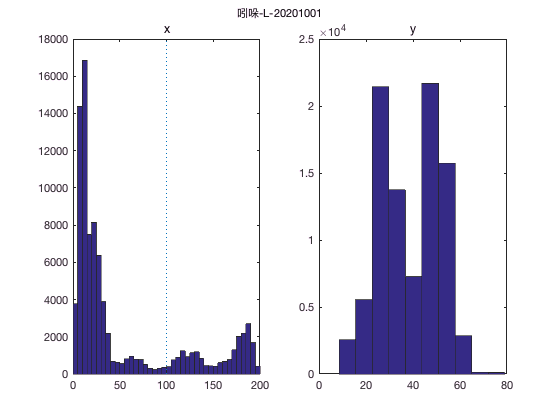

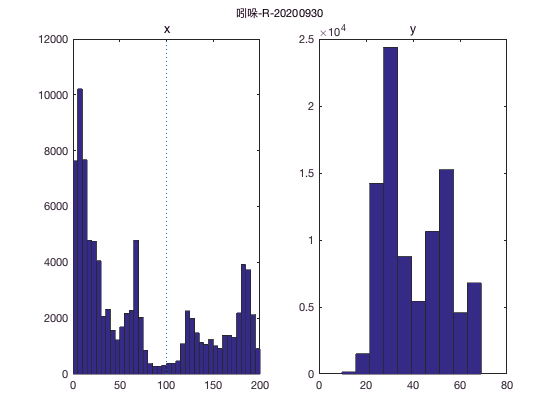

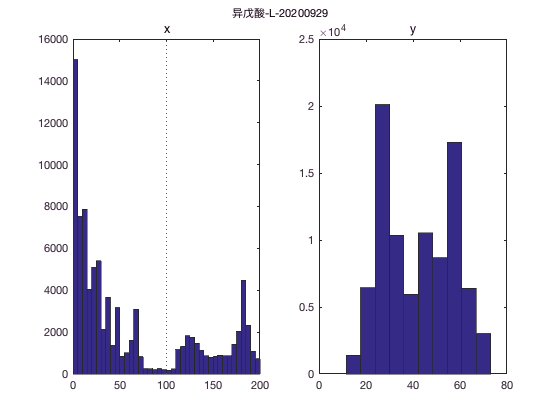

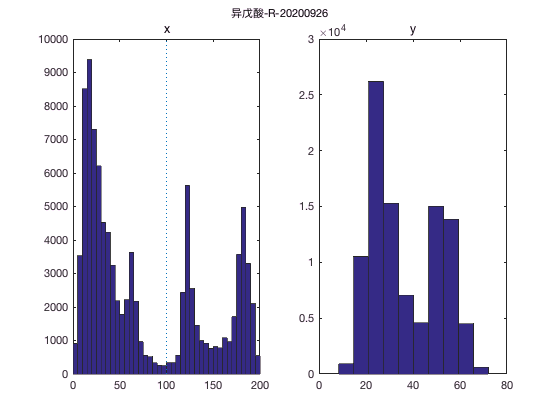

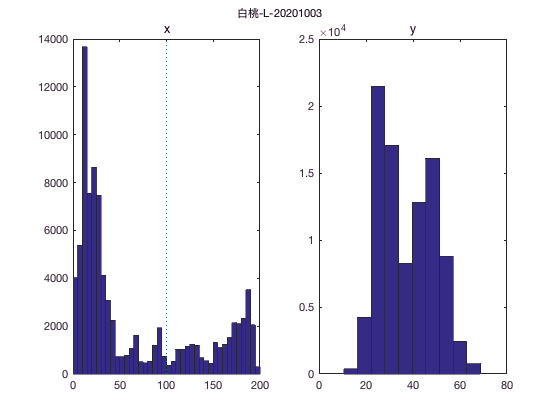

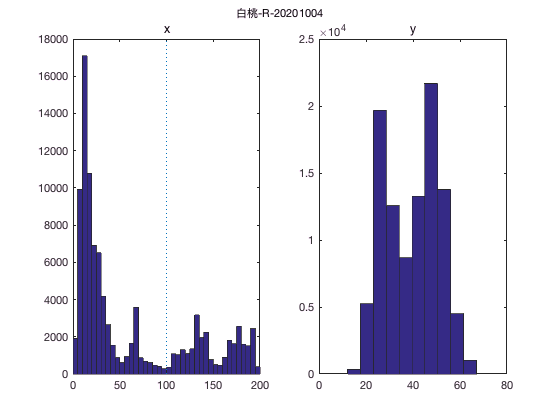

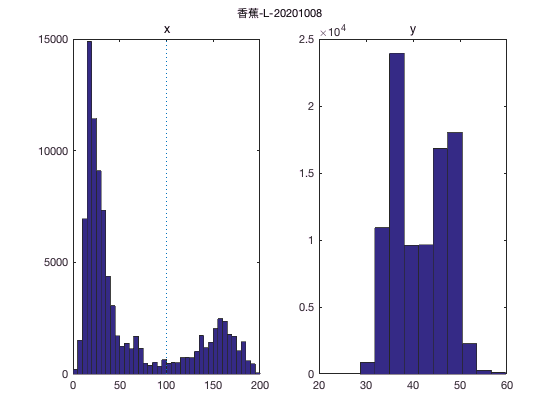

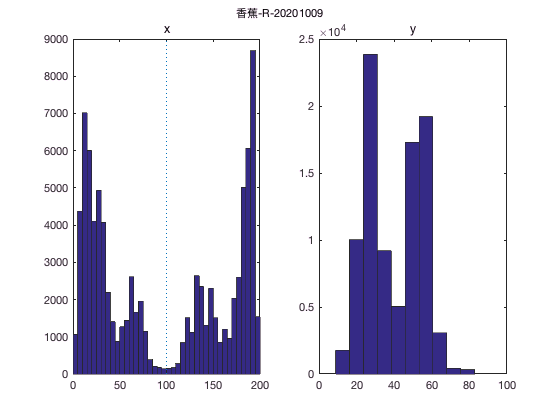

interval=5;
for f=1:length(files)
    data=alldata{f};
    % chisq test
    disp(conditions{f})
    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        % chit-chisquare test
        [pvalue,st]=chit(data,cutl,cutr)
    end
    figure;
    % x方向的分布
    subplot(1,2,1)
    hist(data(:,2),interval/2:interval:200-interval/2);
    line([100 100],get(gca,'Ylim'),'linestyle',':')
    title('x')
    % y方向的分布
    subplot(1,2,2)
    hist(data(:,3));
    title('y')
    suptitle(conditions{f});
end

## 合并4个条件

tic;
interval=10;
% concatenate all the data
data=cell2mat(alldata');
expect=zeros(3,2);
    % chisq test
    disp('all days');

all days


    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr)
        expect(i/10+1,:)=st.O;
    end

   100   100



pvalue = 0

st =     chi2stat: 1.0483e+05
          df: 1
       edges: [0 100 200]
           O: [513527 233660]
           E: [3.7359e+05 3.7359e+05]


    90   110



pvalue = 0

st =     chi2stat: 1.0658e+05
          df: 1
       edges: [0 100 200]
           O: [506619 226995]
           E: [366807 366807]


    80   120



pvalue = 0

st =     chi2stat: 1.1730e+05
          df: 1
       edges: [0 100 200]
           O: [499825 211060]
           E: [3.5544e+05 3.5544e+05]


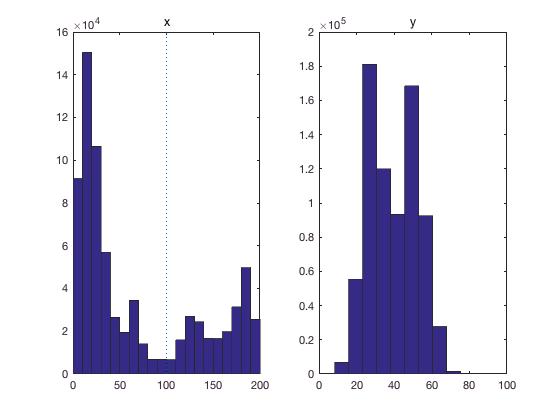


figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')

## 绘制热图

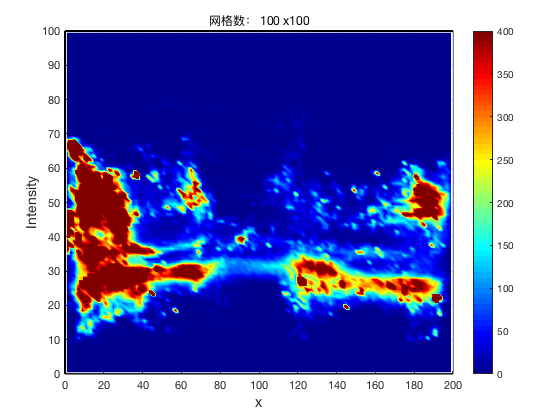

xx=data(:,2);
yy=data(:,3);

% sigma = 0.1;
gridSize = 100;

x=linspace(0,200,gridSize+1);
y=linspace(0,100,gridSize+1);
gridEval = zeros(length(x)-1,length(y)-1);

% 计算每个网格中点的频数
for cnt_x=1:length(x)-1
    for cnt_y=1:length(y)-1
        x_ind=xx>x(cnt_x) & xx<=x(cnt_x+1);                                                    
        xy_ind=yy(x_ind)>y(cnt_y) & yy(x_ind)<=y(cnt_y+1);     
        gridEval(cnt_y, cnt_x)=length(yy(xy_ind));
    end
end

% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end

% 绘制热图
figure;
surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
% 增加z轴会变成三维的
% axis([0 200 0 100 0 100]);
axis([0 200 0 100])
h1 = gca; % 保存句柄，以便后面添加边框
set(gca, 'CLim', [0 400]);
% 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
title(['网格数： ' num2str(gridSize) ' x' num2str(gridSize)]);
xlabel('x','Fontsize',14);
ylabel('y','Fontsize',14);

% 添加颜色条
colormap jet
colorbar;
ylabel('Intensity','Fontsize',14);

% 添加黑色的边框
axes(h1);
line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);

set(gcf,'color',[1 1 1],'paperpositionmode','auto');

toc;

时间已过 72.134438 秒。


## 合并odor两个条件

吲哚-L-20201001


   100   100



pvalue = 0

st =     chi2stat: 1.6239e+04
          df: 1
       edges: [0 100 200]
           O: [100361 82414]
           E: [1.2562e+05 5.7157e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.6420e+04
          df: 1
       edges: [0 100 200]
           O: [98910 80665]
           E: [1.2401e+05 5.5564e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.8544e+04
          df: 1
       edges: [0 100 200]
           O: [96825 77872]
           E: [1.2283e+05 5.1867e+04]


异戊酸-L-20200929


   100   100



pvalue = 0

st =     chi2stat: 2.2164e+04
          df: 1
       edges: [0 100 200]
           O: [99698 88985]
           E: [1.2968e+05 5.9005e+04]


    90   110



pvalue = 0

st =     chi2stat: 2.3047e+04
          df: 1
       edges: [0 100 200]
           O: [98570 88066]
           E: [1.2889e+05 5.7749e+04]


    80   120



pvalue = 0

st =     chi2stat: 2.6146e+04
          df: 1
       edges: [0 100 200]
           O: [95119 84726]
           E: [1.2645e+05 5.3396e+04]


白桃-L-20201003


   100   100



pvalue = 0

st =     chi2stat: 3.4830e+04
          df: 1
       edges: [0 100 200]
           O: [94669 98389]
           E: [1.3268e+05 6.0373e+04]


    90   110



pvalue = 0

st =     chi2stat: 3.7656e+04
          df: 1
       edges: [0 100 200]
           O: [90551 96794]
           E: [1.2938e+05 5.7968e+04]


    80   120



pvalue = 0

st =     chi2stat: 4.2901e+04
          df: 1
       edges: [0 100 200]
           O: [86498 93653]
           E: [1.2666e+05 5.3486e+04]


香蕉-L-20201008


   100   100



pvalue = 0

st =     chi2stat: 4.2072e+03
          df: 1
       edges: [0 100 200]
           O: [112694 69977]
           E: [1.2555e+05 5.7125e+04]


    90   110



pvalue = 0

st =     chi2stat: 4.3692e+03
          df: 1
       edges: [0 100 200]
           O: [111379 68679]
           E: [1.2434e+05 5.5714e+04]


    80   120



pvalue = 0

st =     chi2stat: 5.7472e+03
          df: 1
       edges: [0 100 200]
           O: [109342 66850]
           E: [1.2388e+05 5.2311e+04]


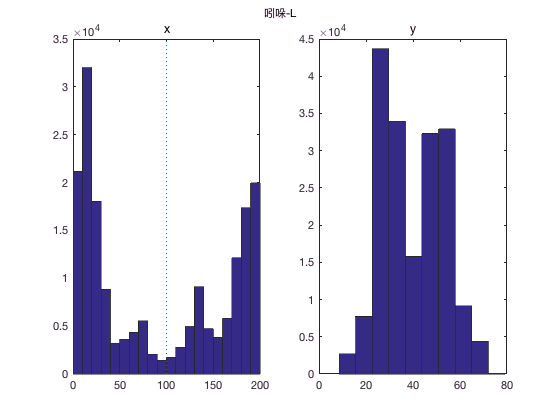

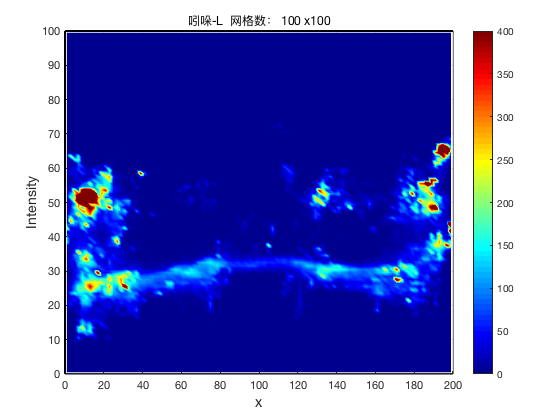

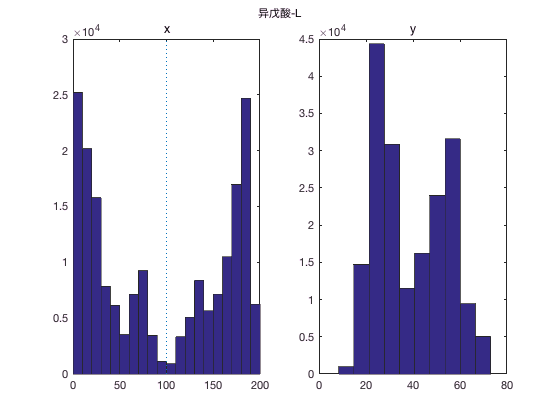

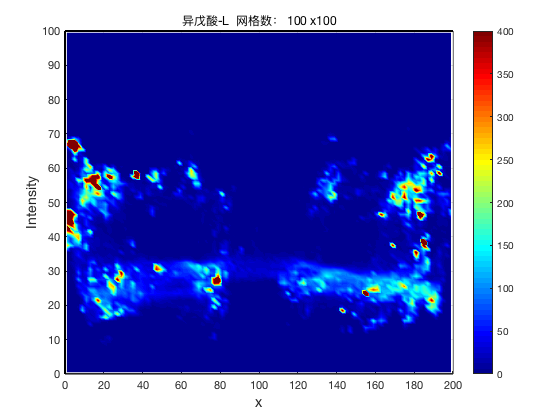

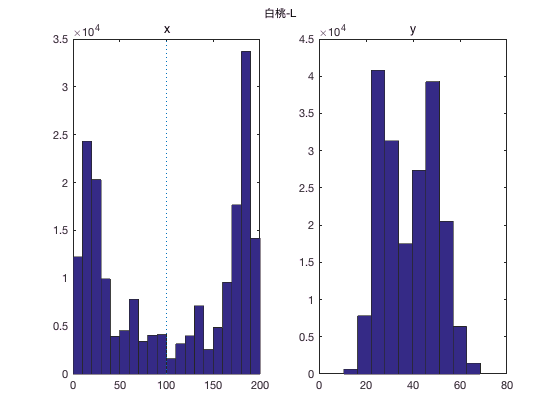

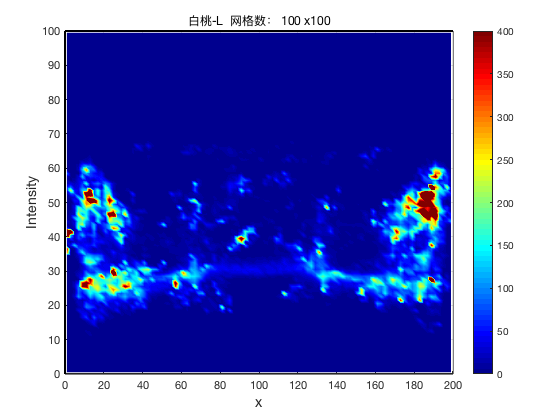

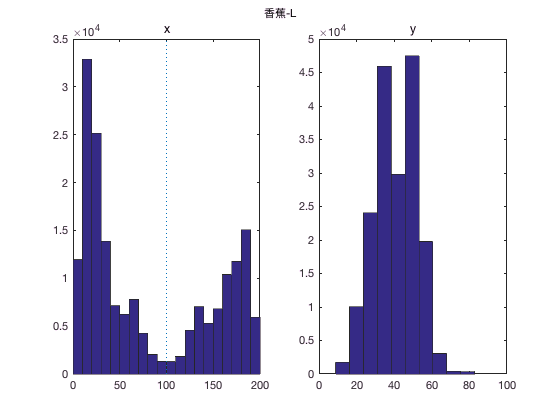

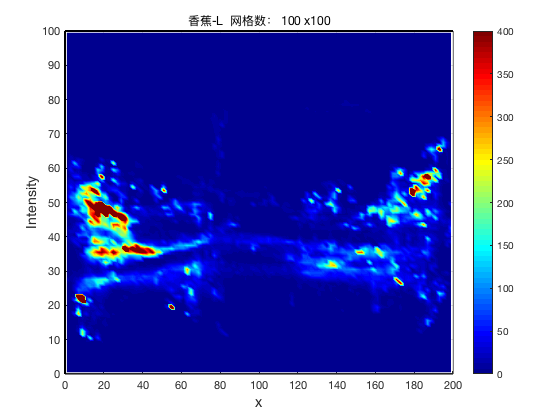

tic;
interval=10;
for odor=2:2:length(conditions)
data=alldata{odor};
data(:,2)=200-data(:,2);
data=[alldata{odor-1};data];

    % chisq test
    disp(conditions{odor-1})
    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr,expect(i/10+1,:))
    end

figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{odor-1};
suptitle(t(1:end-9));
% 绘制热图
xx=data(:,2);
yy=data(:,3);

% sigma = 0.1;
gridSize = 100;

x=linspace(0,200,gridSize+1);
y=linspace(0,100,gridSize+1);
gridEval = zeros(length(x)-1,length(y)-1);

% 计算每个网格中点的频数
for cnt_x=1:length(x)-1
    for cnt_y=1:length(y)-1
        x_ind=xx>x(cnt_x) & xx<=x(cnt_x+1);                                                    
        xy_ind=yy(x_ind)>y(cnt_y) & yy(x_ind)<=y(cnt_y+1);     
        gridEval(cnt_y, cnt_x)=length(yy(xy_ind));
    end
end

% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end

% 绘制热图
figure;
surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
% 增加z轴会变成三维的
% axis([0 200 0 100 0 100]);
axis([0 200 0 100])
h1 = gca; % 保存句柄，以便后面添加边框
set(gca, 'CLim', [0 400]);
% 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
title([t(1:end-9) '  网格数： ' num2str(gridSize) ' x' num2str(gridSize)]);
xlabel('x','Fontsize',14);
ylabel('y','Fontsize',14);

% 添加颜色条
colormap jet
colorbar;
ylabel('Intensity','Fontsize',14);

% 添加黑色的边框
axes(h1);
line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);

set(gcf,'color',[1 1 1],'paperpositionmode','auto');
end

toc;

时间已过 52.543187 秒。


## 合并odor两个条件的（只取前面一段时间）

   100   100



pvalue = 0

st =     chi2stat: 1.9553e+03
          df: 1
       edges: [0 100 200]
           O: [14054 7554]
           E: [10804 10804]


   100   100



pvalue = 3.2995e-17

st =     chi2stat: 71.1567
          df: 1
       edges: [0 100 200]
           O: [8891 10052]
           E: [9.4715e+03 9.4715e+03]


   100   100



pvalue = 3.5172e-35

st =     chi2stat: 153.1696
          df: 1
       edges: [0 100 200]
           O: [10574 12452]
           E: [11513 11513]


   100   100



pvalue = 0

st =     chi2stat: 2.0962e+03
          df: 1
       edges: [0 100 200]
           O: [14024 7333]
           E: [1.0678e+04 1.0678e+04]


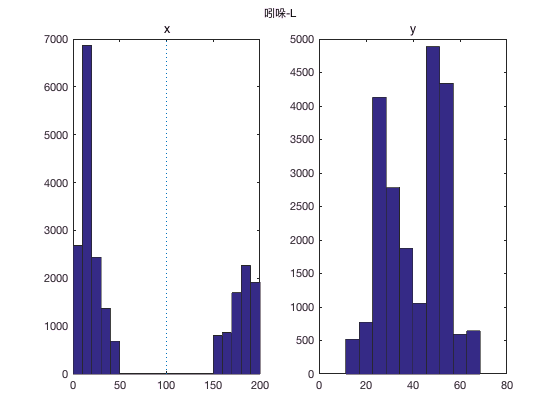

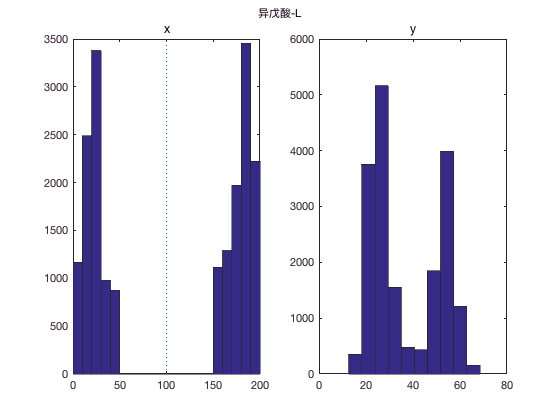

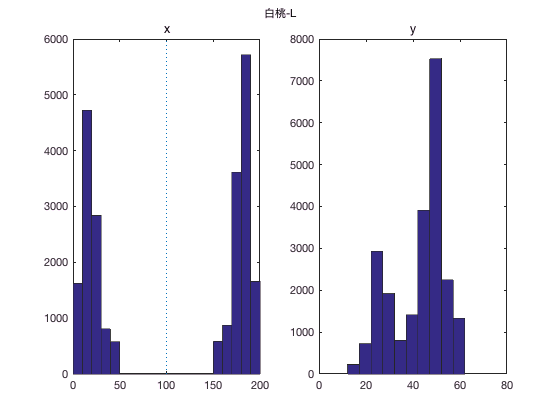

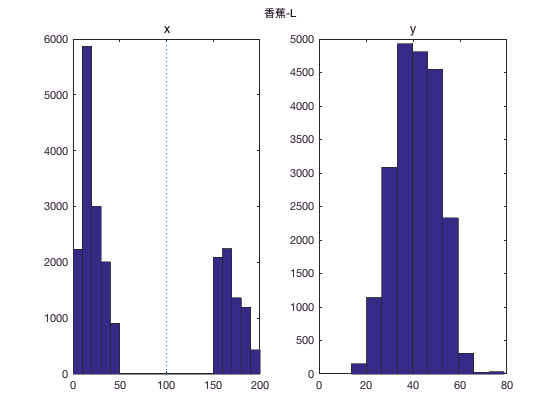

interval=10;
timeint=10;%minute
p1=1;
p2=timeint*60*1000/40;
% 1和3合并为1的方向
for odor=2:2:length(conditions)
data=alldata{odor};
data(:,2)=200-data(:,2);
data=[alldata{odor-1}(p1:p2,:);data(p1:p2,:)];
data=data(data(:,2)<=50|data(:,2)>=150,:);
    % chisq test
    for i=0
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])

        
        
        
        [pvalue,st]=chit(data,cutl,cutr)
    end
figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{odor-1};
suptitle(t(1:end-9));
end

## 分时段的分布直方图

吲哚-L-20201001


-------------


100-100


           0           1
        3940        2209
        4581        1569
        5404         746
        4448        1702
        4372        1778
        5101        1049
        4437        1713
        4689        1461
        4938        1212
        4267        1883
        5528         622
        5072        1078
        4701        1449
        4574        1576
        3949        1003



   2.3757e+03



     0



-------------


-------------


90-110


           0           1
        3885        2264
        4559        1591
        5362         788
        4422        1728
        4155        1995
        5040        1110
        4391        1759
        4665        1485
        4912        1238
        4228        1922
        5516         634
        5049        1101
        4674        1476
        4535        1615
        3933        1019



   2.5218e+03



     0



-------------


-------------


80-120


           0           1
        3833        2316
        4537        1613
        5325         825
        4400        1750
        4066        2084
        4974        1176
        4370        1780
        4645        1505
        4840        1310
        4181        1969
        5507         643
        5028        1122
        4652        1498
        4505        1645
        3922        1030



   2.5688e+03



     0



-------------


-------------


70-130


           0           1
        3714        2435
        4503        1647
        5283         867
        4370        1780
        3838        2312
        4826        1324
        4333        1817
        4593        1557
        4672        1478
        4046        2104
        5432         718
        4967        1183
        4612        1538
        4439        1711
        3874        1078



   2.7099e+03



     0



-------------


-------------


60-140


           0           1
        3419        2730
        4440        1710
        5196         954
        4290        1860
        3680        2470
        4719        1431
        4280        1870
        4499        1651
        4460        1690
        3921        2229
        5326         824
        4866        1284
        4532        1618
        4340        1810
        3779        1173



   2.9406e+03



     0



-------------


-------------


50-150


           0           1
        3211        2938
        4380        1770
        5123        1027
        4215        1935
        3530        2620
        4633        1517
        4227        1923
        4427        1723
        4349        1801
        3805        2345
        5277         873
        4763        1387
        4456        1694
        4267        1883
        3721        1231



   3.2138e+03



     0



-------------


吲哚-R-20200930


-------------


100-100


           0           1
        3359        2790
        2751        3399
        3642        2508
        3398        2752
        3986        2164
        3622        2528
        5122        1028
        4933        1217
        5168         982
        3747        2403
        3175        2975
        4774        1376
        4794        1356
        3479        2671
        5413         210



   8.4607e+03



     0



-------------


-------------


90-110


           0           1
        3298        2851
        2691        3459
        3596        2554
        3347        2803
        3931        2219
        3595        2555
        5089        1061
        4902        1248
        5139        1011
        3709        2441
        3120        3030
        4757        1393
        4753        1397
        3427        2723
        5405         218



   8.6168e+03



     0



-------------


-------------


80-120


           0           1
        3237        2912
        2624        3526
        3543        2607
        3296        2854
        3886        2264
        3556        2594
        5057        1093
        4850        1300
        5109        1041
        3671        2479
        3064        3086
        4739        1411
        4712        1438
        3371        2779
        5395         228



   8.7709e+03



     0



-------------


-------------


70-130


           0           1
        3112        3037
        2483        3667
        3055        3095
        3210        2940
        3557        2593
        3400        2750
        4959        1191
        4578        1572
        4869        1281
        3575        2575
        2707        3443
        4502        1648
        4622        1528
        3216        2934
        5385         238



   9.1126e+03



     0



-------------


-------------


60-140


           0           1
        2709        3440
        2188        3962
        2336        3814
        2965        3185
        2773        3377
        3029        3121
        3953        2197
        3793        2357
        4735        1415
        3431        2719
        2402        3748
        4097        2053
        4089        2061
        2290        3860
        5360         263



   9.6811e+03



     0



-------------


-------------


50-150


           0           1
        2097        4052
        1799        4351
        2120        4030
        2772        3378
        2611        3539
        2872        3278
        3021        3129
        3659        2491
        4612        1538
        3312        2838
        2200        3950
        4022        2128
        3931        2219
        1933        4217
        5339         284



   1.1241e+04



     0



-------------


异戊酸-L-20200929


-------------


100-100


           0           1
        1959        4190
        2282        3868
        4415        1735
        5049        1101
        5000        1150
        4314        1836
        3759        2391
        4912        1238
        4857        1293
        5886         264
        4389        1761
        4794        1356
        4087        2063
        4872        1278
        3286         744



   1.1827e+04



     0



-------------


-------------


90-110


           0           1
        1925        4224
        2241        3909
        4389        1761
        4885        1265
        4983        1167
        4300        1850
        3732        2418
        4893        1257
        4838        1312
        5879         271
        4377        1773
        4781        1369
        4068        2082
        4849        1301
        3264         766



   1.1724e+04



     0



-------------


-------------


80-120


           0           1
        1882        4267
        2198        3952
        4365        1785
        4744        1406
        4962        1188
        4283        1867
        3702        2448
        4878        1272
        4817        1333
        5874         276
        4363        1787
        4767        1383
        4051        2099
        4830        1320
        3240         790



   1.1720e+04



     0



-------------


-------------


70-130


           0           1
        1741        4408
        1980        4170
        4312        1838
        4711        1439
        4915        1235
        4251        1899
        3616        2534
        4840        1310
        4781        1369
        5862         288
        4337        1813
        4742        1408
        4008        2142
        4576        1574
        3206         824



   1.2400e+04



     0



-------------


-------------


60-140


           0           1
        1370        4779
        1336        4814
        4165        1985
        4657        1493
        4282        1868
        3949        2201
        2511        3639
        4677        1473
        4675        1475
        5832         318
        4280        1870
        4501        1649
        3418        2732
        4395        1755
        3133         897



   1.5511e+04



     0



-------------


-------------


50-150


           0           1
        1238        4911
        1170        4980
        4085        2065
        4615        1535
        4194        1956
        3707        2443
        2320        3830
        4445        1705
        4492        1658
        5818         332
        4239        1911
        4325        1825
        3339        2811
        4288        1862
        3058         972



   1.5744e+04



     0



-------------


异戊酸-R-20200926


-------------


100-100


           1           0
        2717        3432
        2715        3435
        3810        2340
        2863        3287
        4256        1894
        3505        2645
        3592        2558
        4577        1573
        2668        3482
        5990         160
        2882        3268
        4349        1801
        4472        1678
        3392        2758
        5071        1079
        5823         327
          33         120



   1.2411e+04



     0



-------------


-------------


90-110


           1           0
        2677        3472
        2671        3479
        3776        2374
        2832        3318
        4238        1912
        3444        2706
        3535        2615
        4548        1602
        2641        3509
        5988         162
        2865        3285
        4315        1835
        4436        1714
        3340        2810
        5053        1097
        5817         333
          31         122



   1.2574e+04



     0



-------------


-------------


80-120


           1           0
        2632        3517
        2629        3521
        3747        2403
        2805        3345
        4222        1928
        3387        2763
        3385        2765
        4512        1638
        2612        3538
        5986         164
        2829        3321
        4273        1877
        4191        1959
        3284        2866
        5030        1120
        5811         339
          29         124



   1.2628e+04



     0



-------------


-------------


70-130


           1           0
        2519        3630
        2562        3588
        3695        2455
        2747        3403
        4192        1958
        3285        2865
        3241        2909
        4400        1750
        2481        3669
        5982         168
        2776        3374
        4153        1997
        3907        2243
        3140        3010
        4939        1211
        5801         349
          23         130



   1.2915e+04



     0



-------------


-------------


60-140


           1           0
        2050        4099
        2361        3789
        2814        3336
        2380        3770
        3485        2665
        2836        3314
        2643        3507
        4238        1912
        1775        4375
        5975         175
        2506        3644
        3993        2157
        3577        2573
        2965        3185
        4634        1516
        5788         362
          19         134



   1.5701e+04



     0



-------------


-------------


50-150


           1           0
        1477        4672
        2195        3955
        2635        3515
        2221        3929
        3389        2761
        2451        3699
        2352        3798
        4101        2049
        1638        4512
        5968         182
        2381        3769
        3856        2294
        3336        2814
        2763        3387
        3512        2638
        5751         399
          15         138



   1.6572e+04



     0



-------------


白桃-L-20201003


-------------


100-100


           0           1
        2890        3259
        3783        2367
        3406        2744
        4271        1879
        3701        2449
        4501        1649
        4223        1927
        4865        1285
        4299        1851
        5278         872
        5313         837
        4297        1853
        4656        1494
        5366         784
        5553         597
          53           0



   6.7595e+03



     0



-------------


-------------


90-110


           0           1
        2846        3303
        3743        2407
        3372        2778
        3567        2583
        3659        2491
        3475        2675
        3909        2241
        4852        1298
        4285        1865
        5013        1137
        5267         883
        4236        1914
        4630        1520
        5361         789
        5526         624
          53           0



   7.2755e+03



     0



-------------


-------------


80-120


           0           1
        2808        3341
        3708        2442
        3338        2812
        3443        2707
        3635        2515
        3100        3050
        3528        2622
        4841        1309
        4274        1876
        4754        1396
        5219         931
        4187        1963
        4323        1827
        5356         794
        5510         640
          53           0



   7.5890e+03



     0



-------------


-------------


70-130


           0           1
        2749        3400
        3653        2497
        3293        2857
        3313        2837
        3570        2580
        3040        3110
        3392        2758
        4820        1330
        4257        1893
        4720        1430
        5195         955
        4164        1986
        4077        2073
        5340         810
        5469         681
          53           0



   7.8261e+03



     0



-------------


-------------


60-140


           0           1
        2589        3560
        3511        2639
        3175        2975
        2613        3537
        3430        2720
        2916        3234
        3214        2936
        4690        1460
        4213        1937
        4557        1593
        5059        1091
        3960        2190
        3943        2207
        5313         837
        5168         982
          53           0



   8.3003e+03



     0



-------------


-------------


50-150


           0           1
        2325        3824
        3404        2746
        3092        3058
        2491        3659
        3351        2799
        2845        3305
        3111        3039
        4648        1502
        4183        1967
        4490        1660
        4983        1167
        3908        2242
        3691        2459
        5298         852
        5025        1125
          53           0



   8.7284e+03



     0



-------------


白桃-R-20201004


-------------


100-100


           0           1
        3695        2454
        3562        2588
        4502        1648
        3585        2565
        4129        2021
        4136        2014
        4655        1495
        4787        1363
        4879        1271
        3537        2613
        5059        1091
        4801        1349
        4858        1292
        4950        1200
        5126        1024
        4420        1730
        1860         495



   3.9603e+03



     0



-------------


-------------


90-110


           0           1
        3668        2481
        3515        2635
        4481        1669
        3550        2600
        4070        2080
        4105        2045
        4624        1526
        4767        1383
        4860        1290
        3508        2642
        4987        1163
        4773        1377
        4807        1343
        4938        1212
        5115        1035
        4231        1919
        1847         508



   3.9594e+03



     0



-------------


-------------


80-120


           0           1
        3640        2509
        3465        2685
        4462        1688
        3518        2632
        4039        2111
        4080        2070
        4604        1546
        4754        1396
        4846        1304
        3486        2664
        4558        1592
        4618        1532
        4783        1367
        4904        1246
        5104        1046
        4057        2093
        1836         519



   3.6608e+03



     0



-------------


-------------


70-130


           0           1
        3584        2565
        3400        2750
        4430        1720
        3473        2677
        4006        2144
        4013        2137
        4580        1570
        4705        1445
        4814        1336
        3458        2692
        4019        2131
        4464        1686
        4757        1393
        4854        1296
        4853        1297
        3955        2195
        1825         530



   3.3582e+03



     0



-------------


-------------


60-140


           0           1
        3457        2692
        3238        2912
        4319        1831
        3355        2795
        3838        2312
        3854        2296
        4376        1774
        3840        2310
        4732        1418
        3336        2814
        3698        2452
        3932        2218
        4463        1687
        4547        1603
        4133        2017
        3079        3071
        1752         603



   2.8302e+03



     0



-------------


-------------


50-150


           0           1
        3383        2766
        3147        3003
        4228        1922
        3293        2857
        3759        2391
        3768        2382
        4320        1830
        3719        2431
        4685        1465
        3275        2875
        3599        2551
        3783        2367
        4417        1733
        4290        1860
        4090        2060
        2942        3208
        1703         652



   2.7738e+03



     0



-------------


香蕉-L-20201008


-------------


100-100


           1           0
        3684        2465
        4640        1510
        4023        2127
        4969        1181
        3997        2153
        4645        1505
        4393        1757
        4502        1648
        4675        1475
        5072        1078
        4719        1431
        5003        1147
        4734        1416
        5067        1083
        5202         948
         211           0



   2.4446e+03



     0



-------------


-------------


90-110


           1           0
        3582        2567
        4402        1748
        3968        2182
        4937        1213
        3956        2194
        4612        1538
        4334        1816
        4410        1740
        4646        1504
        4944        1206
        4666        1484
        4970        1180
        4686        1464
        5036        1114
        5182         968
         211           0



   2.5137e+03



     0



-------------


-------------


80-120


           1           0
        3508        2641
        4354        1796
        3928        2222
        4908        1242
        3805        2345
        4584        1566
        4283        1867
        4336        1814
        4623        1527
        4903        1247
        4611        1539
        4947        1203
        4653        1497
        4806        1344
        5168         982
         211           0



   2.5731e+03



     0



-------------


-------------


70-130


           1           0
        3459        2690
        4313        1837
        3899        2251
        4530        1620
        3624        2526
        4466        1684
        4058        2092
        4228        1922
        4591        1559
        4710        1440
        4533        1617
        4909        1241
        4603        1547
        4704        1446
        5151         999
         211           0



   2.4857e+03



     0



-------------


-------------


60-140


           1           0
        3377        2772
        4264        1886
        3846        2304
        4435        1715
        3346        2804
        4126        2024
        3654        2496
        3921        2229
        4508        1642
        4578        1572
        4208        1942
        4720        1430
        4340        1810
        4529        1621
        5117        1033
         211           0



   2.6898e+03



     0



-------------


-------------


50-150


           1           0
        3127        3022
        4222        1928
        3776        2374
        4341        1809
        3201        2949
        3979        2171
        3272        2878
        3745        2405
        4442        1708
        4484        1666
        4012        2138
        4639        1511
        4205        1945
        3825        2325
        5079        1071
         211           0



   3.1898e+03



     0



-------------


香蕉-R-20201009


-------------


100-100


           0           1
        2461        3688
        3284        2866
        2974        3176
        3209        2941
        3588        2562
        4313        1837
        3582        2568
        2949        3201
        3404        2746
        3923        2227
        3092        3058
        3887        2263
        3807        2343
         688        5462
        1892        2218



   6.5294e+03



     0



-------------


-------------


90-110


           0           1
        2440        3709
        3242        2908
        2942        3208
        3157        2993
        3570        2580
        4293        1857
        3556        2594
        2930        3220
        3386        2764
        3911        2239
        3079        3071
        3881        2269
        3780        2370
         682        5468
        1890        2220



   6.4897e+03



     0



-------------


-------------


80-120


           0           1
        2412        3737
        3073        3077
        2874        3276
        3100        3050
        3544        2606
        4259        1891
        3512        2638
        2899        3251
        3349        2801
        3895        2255
        3056        3094
        3870        2280
        3745        2405
         673        5477
        1888        2222



   6.4367e+03



     0



-------------


-------------


70-130


           0           1
        2310        3839
        2804        3346
        2706        3444
        2338        3812
        3111        3039
        4147        2003
        3237        2913
        2721        3429
        3021        3129
        3822        2328
        2883        3267
        3835        2315
        3582        2568
         641        5509
        1882        2228



   6.3559e+03



     0



-------------


-------------


60-140


           0           1
        2137        4012
        2006        4144
        2168        3982
        1664        4486
        2667        3483
        3987        2163
        3009        3141
        2507        3643
        2646        3504
        3716        2434
        2776        3374
        3794        2356
        3269        2881
         610        5540
        1811        2299



   7.1843e+03



     0



-------------


-------------


50-150


           0           1
        2024        4125
        1738        4412
        1937        4213
        1330        4820
        2237        3913
        3555        2595
        2796        3354
        2391        3759
        2484        3666
        3640        2510
        2697        3453
        3759        2391
        3113        3037
         587        5563
        1772        2338



   7.2675e+03



     0



-------------


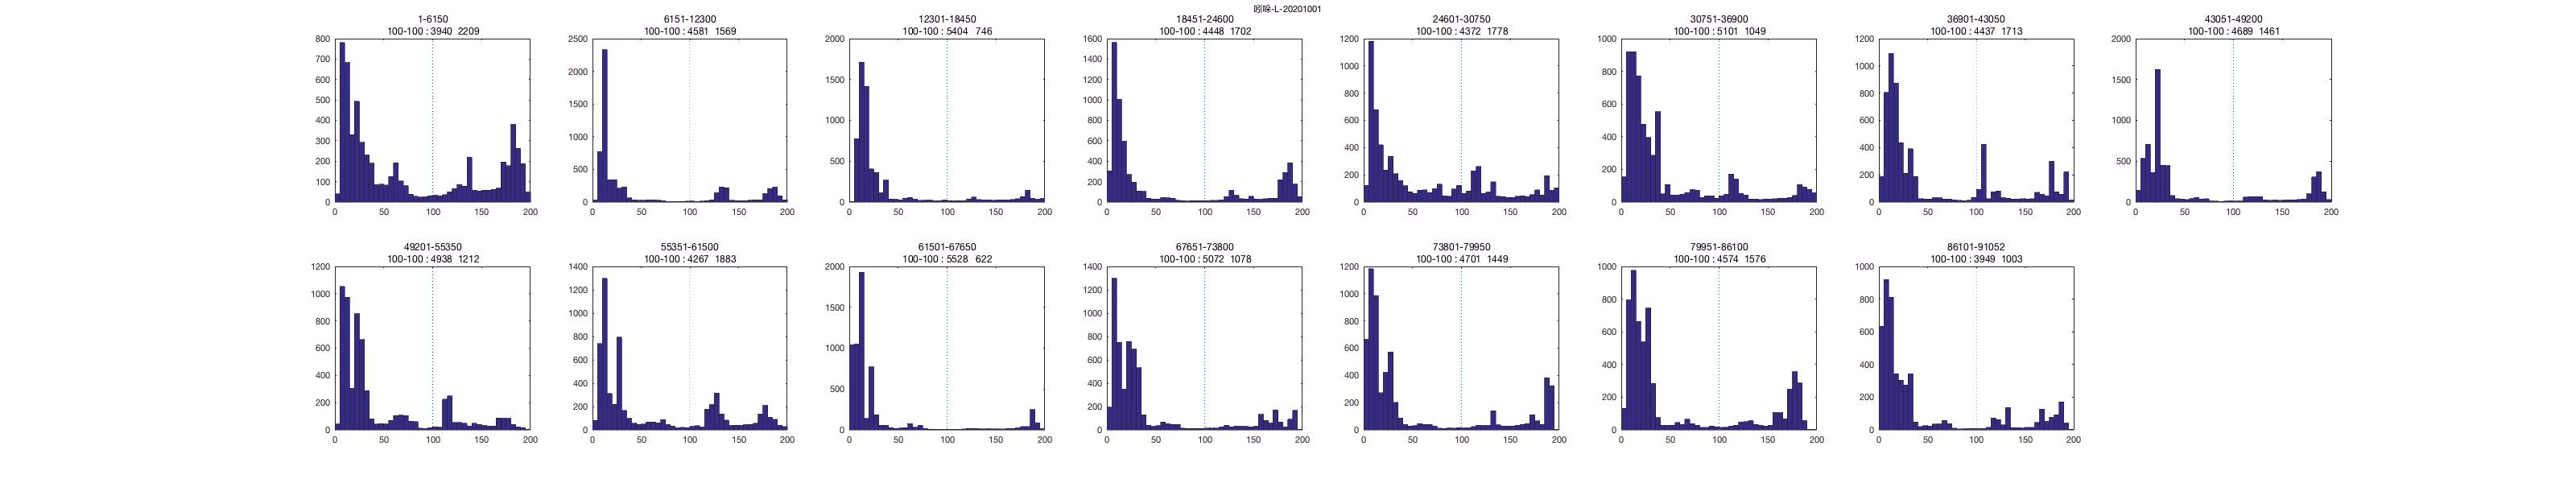

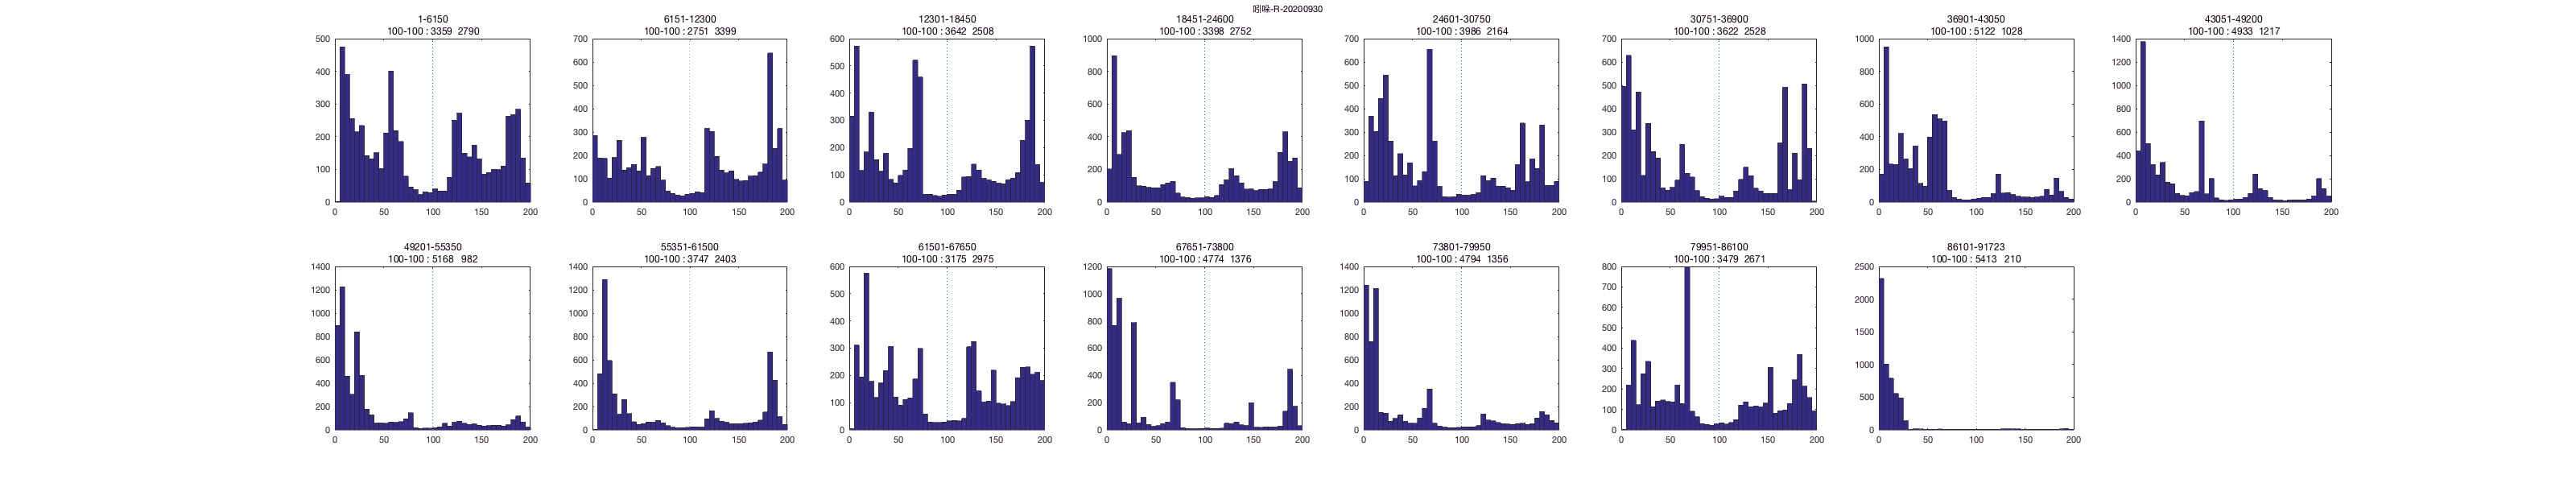

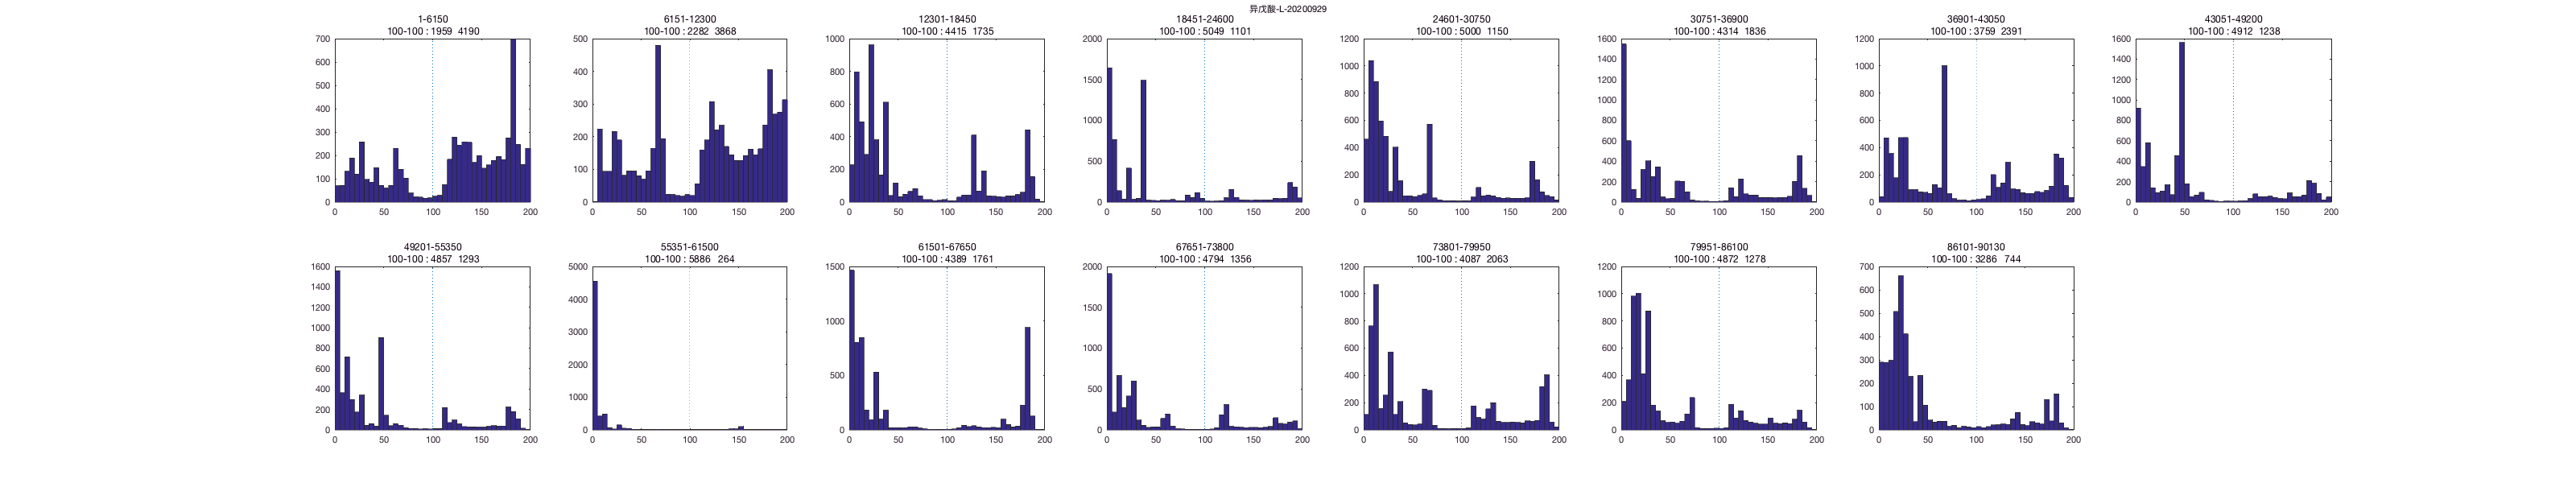

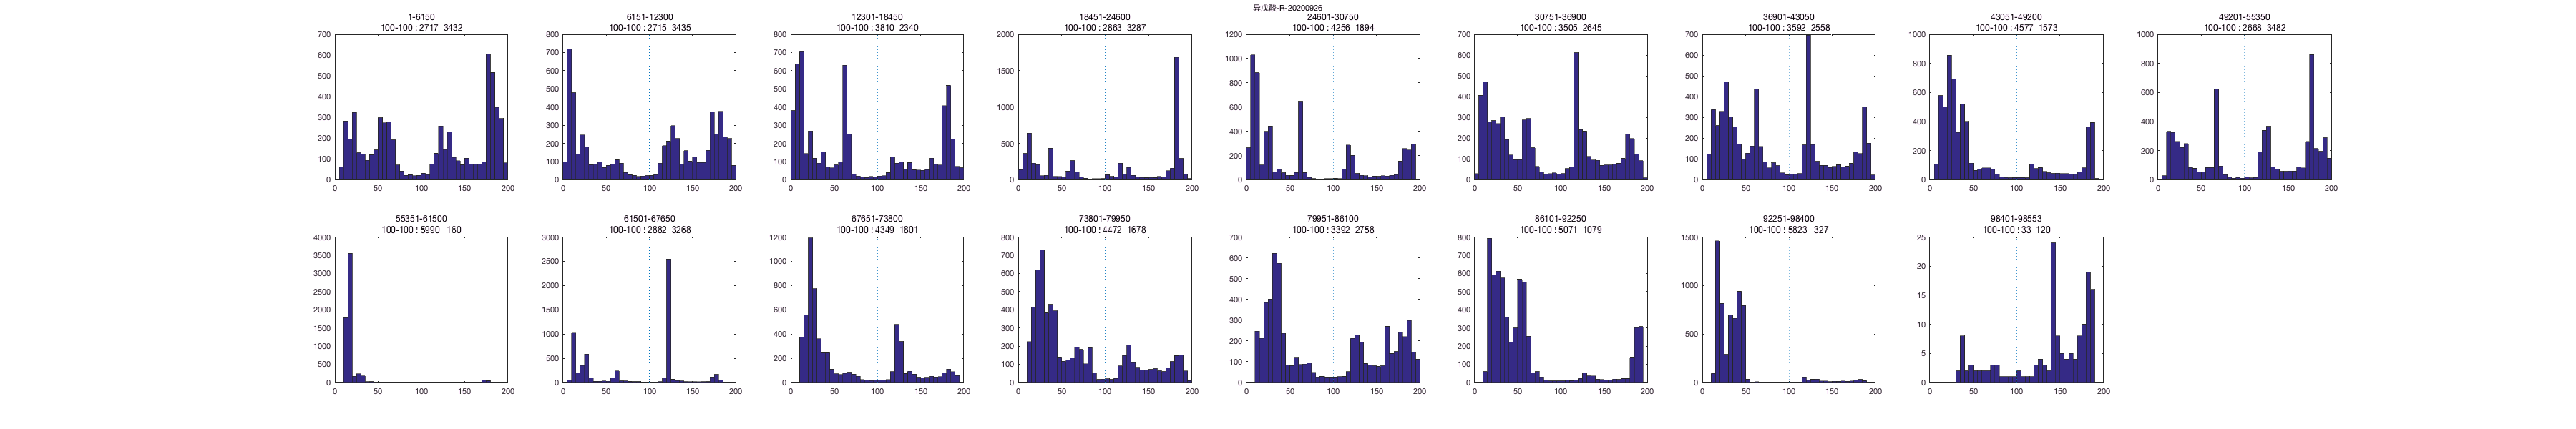

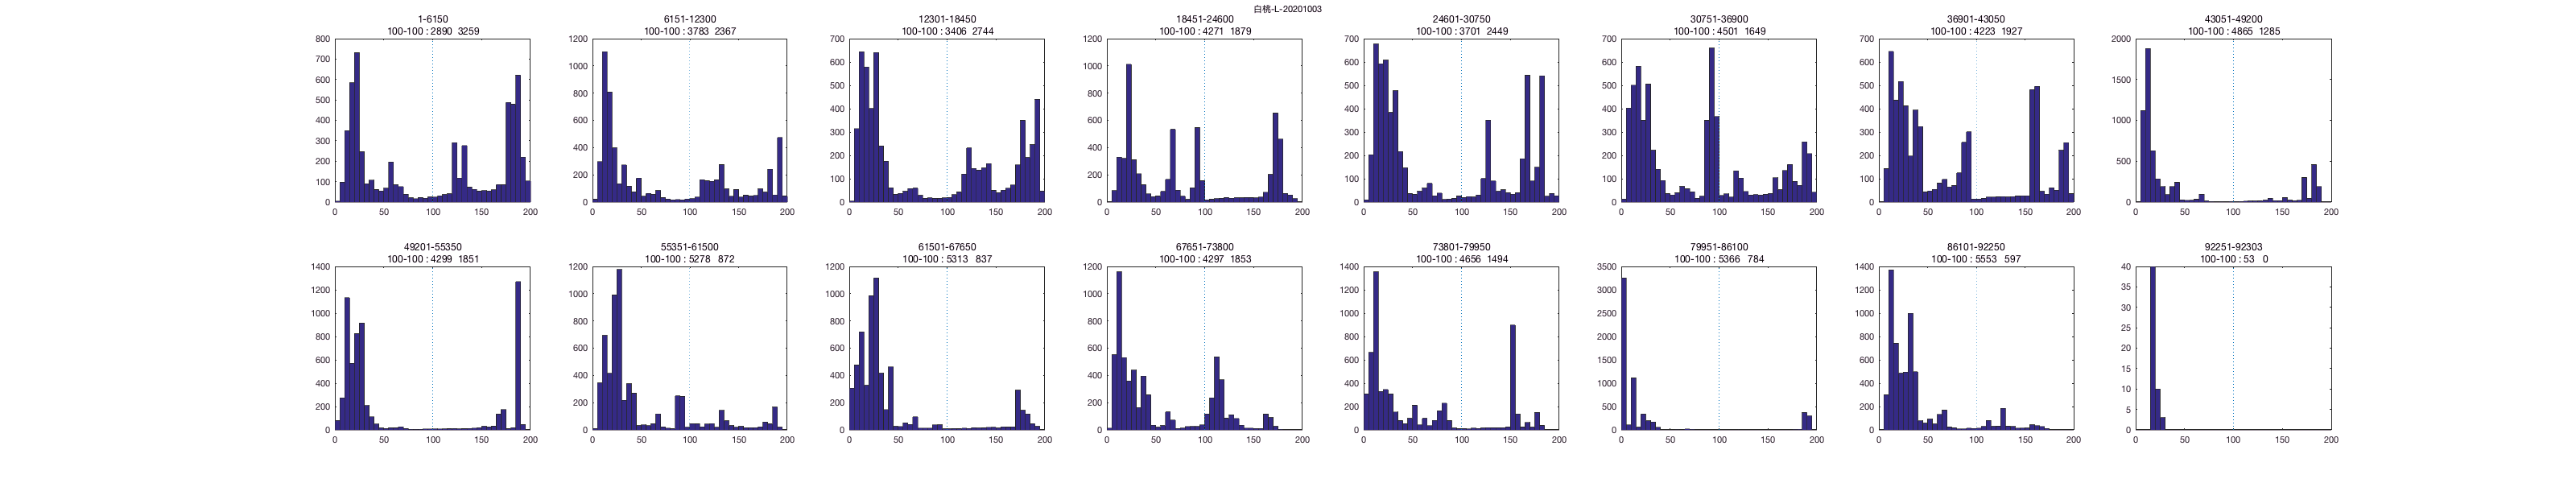

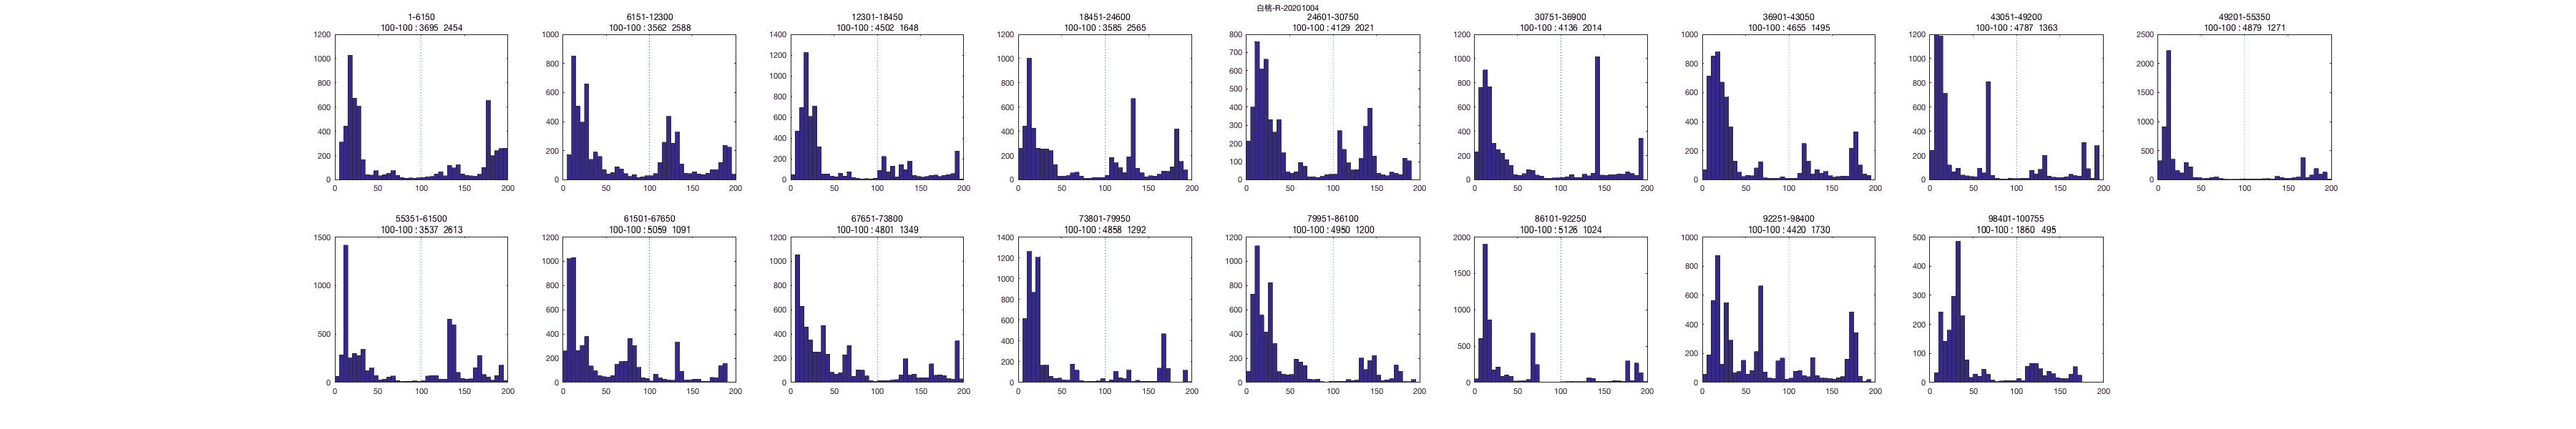

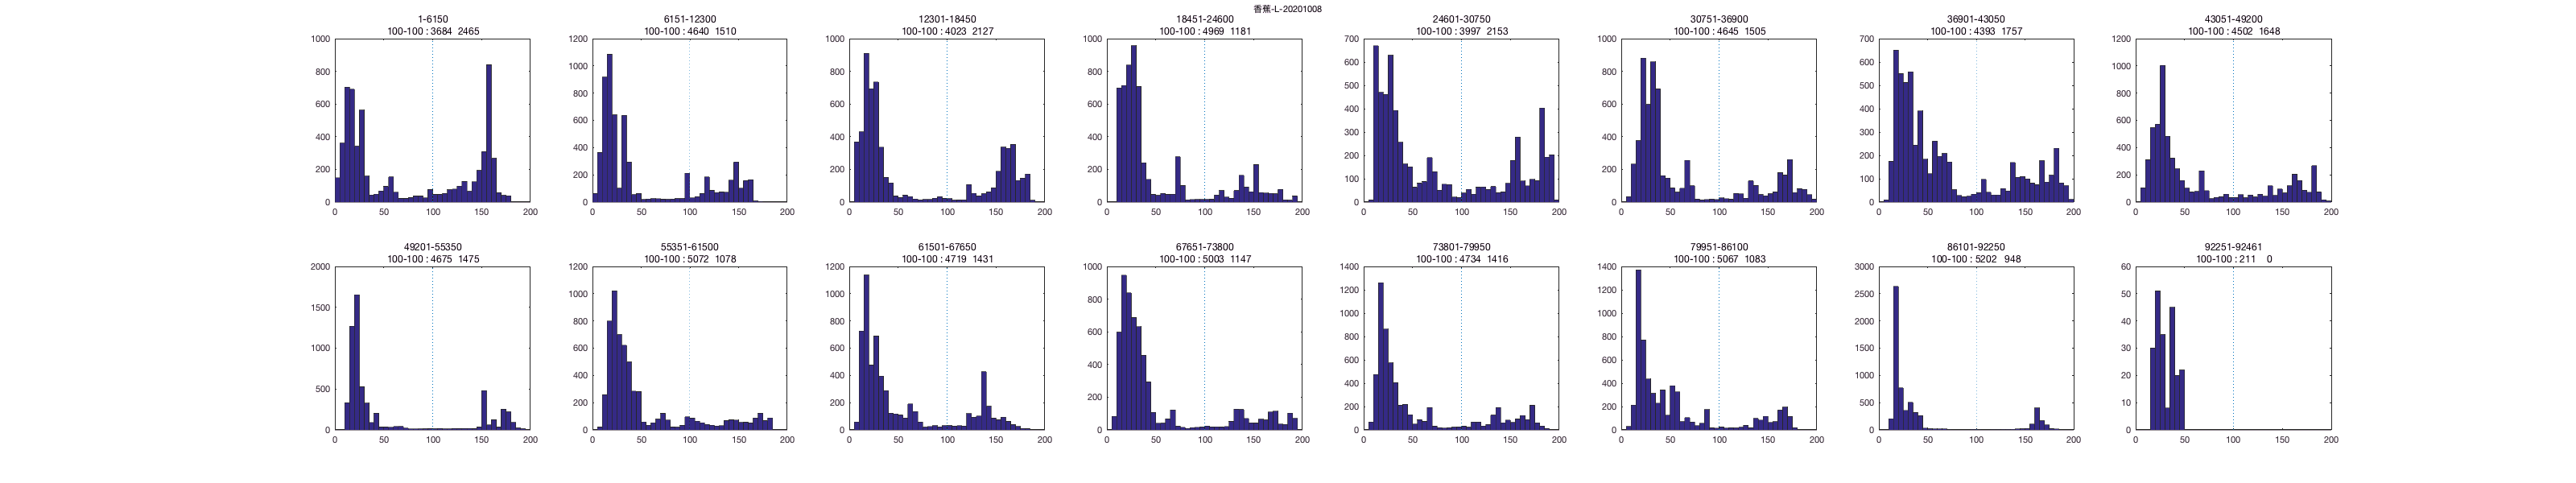

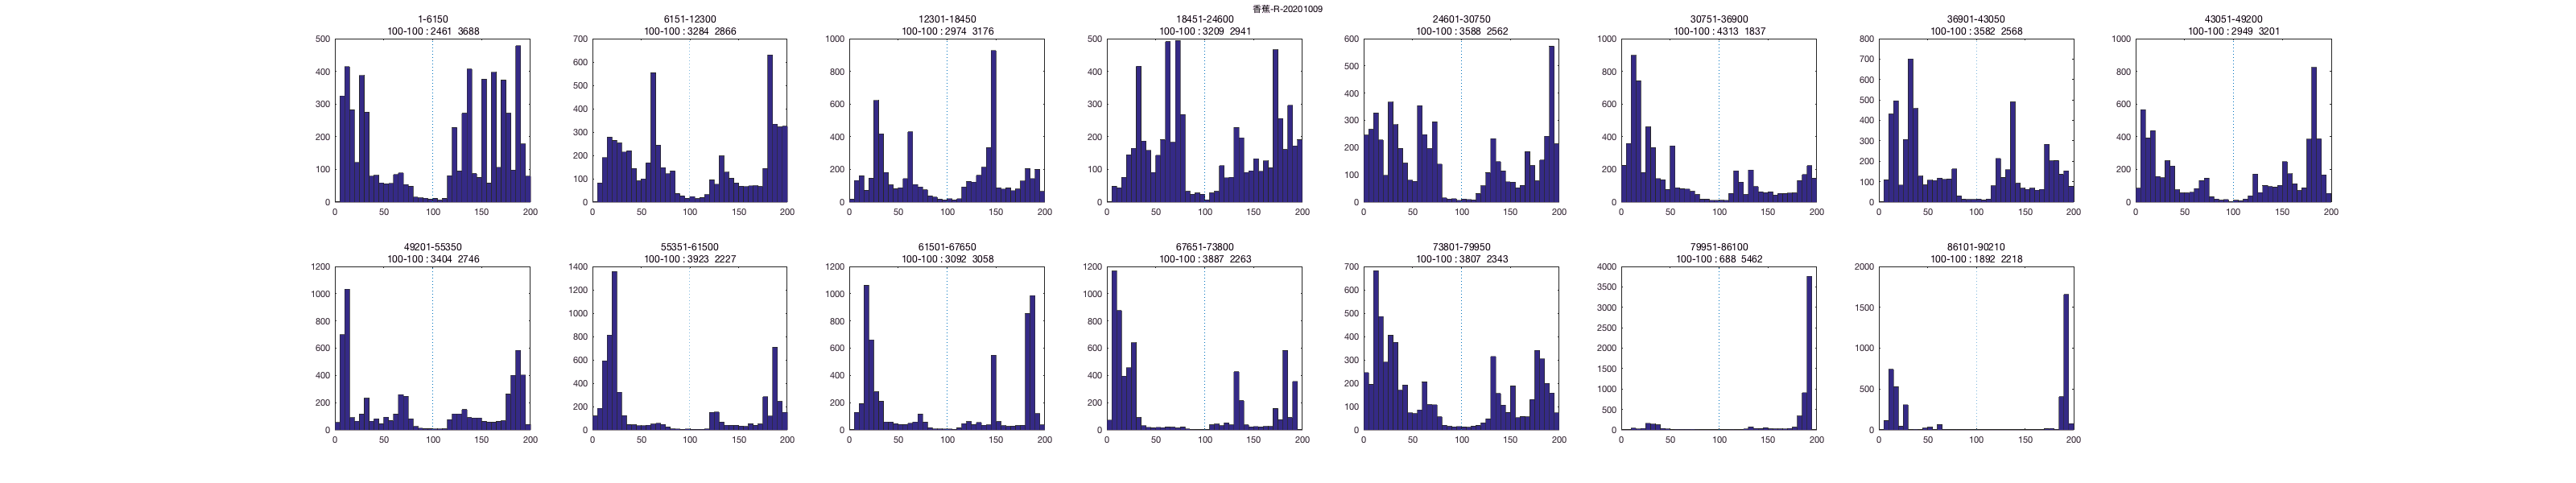

timeint=4.1;%minute
p=timeint*60*1000/40;
interval=5;
% plot each day
for f=1:length(files)
    data=alldata{f};
    l=length(data(:,2));
    plots=ceil(l/p);
    figure;
    set(gcf,'position',[1280,720,ceil(plots/2)*400,2*300]);
    disp('===========================')
    disp(conditions{f})
    disp('===========================')
    for j=0:10:50
        timelab=zeros(1,l);
        leftright=timelab;
        cutl=100-j;
        cutr=100+j;
        leftright(data(:,2)<cutl)=1;
        leftright(data(:,2)>cutl)=2;
        for i=1:plots
            timelab(p*(i-1)+1:min(p*i,l))=i;                     
        end
        timelab(leftright==0)=[];
        leftright(leftright==0)=[];
        [tbl,chi2,pvalue] = crosstab(timelab,leftright);
        disp('-------------')
        disp([num2str(cutl) '-' num2str(cutr)])
        disp(tbl)
        disp(chi2)
        disp(pvalue)
        disp('-------------')

    end
    % subplot each bin
    for i=1:plots
        subplot(2,ceil(plots/2),i)
        hist(data(p*(i-1)+1:min(p*i,l),2),interval/2:interval:200-interval/2)
        line([100 100],get(gca,'Ylim'),'linestyle',':')
%         disp('-------------')
%         disp([num2str(p*(i-1)+1) '-' num2str(min(p*i,l))])
%         
            % chisq test
        for j=0%:10:20
            cutl=100-j;
            cutr=100+j;
%             disp([cutl cutr])
            [pvalue,st]=chit(data(p*(i-1)+1:min(p*i,l),:),cutl,cutr);
        end
%         disp('-------------')
        
        title({[num2str(p*(i-1)+1) '-' num2str(min(p*i,l))];[num2str(cutl) '-' num2str(cutr) ' : ' num2str(st.O)]})
    end
    suptitle({conditions{f};''});
end